# Explore some Fundamental Symbolic Computing syntax: 

We'll look at some fundamental syntax (patterns) for doing `Symbolic` computing. We'll look at how to create and manipulate symbolic expressions.  Specifically we, we'll:

- create symbolic expressions

- create symbolic functions

- Plot symbolic expressions

- Differentiate               

- Integrate 

- computer Laplace transforms

- Solve ODEs

- *****YES:  **apply Lagranges equation to a spring mass damper system

While you're doing this tutorial, don't forget to leverage the MATLAB help browser:

Look for this icon 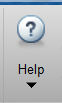 on the MATLAB desktop and click on it often !  The help browser lets you search using "plain english" keywords. For example, if you wanted to know how to differentiate symbolic expressions, you could start by typing in this search:

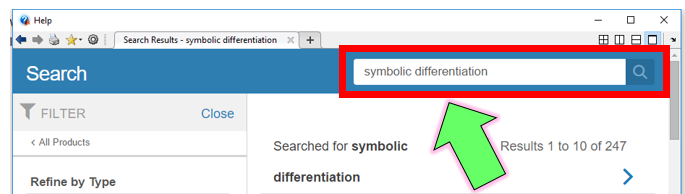

The Help Browser also has a collection of "Getting started" Tutorials !

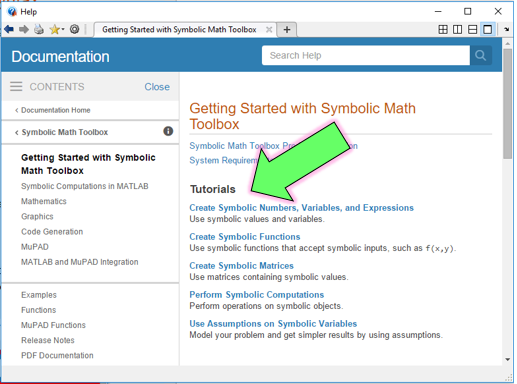

`10-Jan-2017 : Bradley Horton, bradley.horton@mathworks.com.au`            

## **A symbolic expression:  ( aka a **`sym`**)**

syms x y theta

And now you can create a symbolic expressions using that `sym` variable:

f    = exp(-y)/x + 3*x^2
R    = [   cos(theta),  -sin(theta),       f;
           sin(theta),   cos(theta),       0;
                0,        0,               1;
       ]

Using familiar MATLAB indexing syntax, we can extract the 1st row and 3rd column of the R matrix:

some_expression = R(1,3)

If I have a symbolic expression and I want to evaluate it with some numerical inputs, you would use the `subs()` function.  Eg: consider the expression stored in g :

g    = 5*x + 7

If I want to evaluate this expression with *x=2*, then we'd use the `subs()` function:

some_value = subs(g,x,2)  

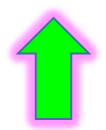      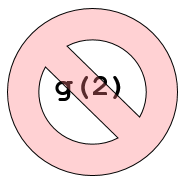 

## **A symbolic function:  (aka a **`symfun`**)**

Now create some sym variables

syms x y

We can construct a `symfun` symbolic function variable using this syntax:

f(x,y) = 5*x + (x^2)*(y^2)

So evaluate:

-  f(x=2, y=5):   and this should give us:   `2*5 + (4)*(25) == 110`

Sf_val = f(2,5)

If I wanted to "extract" the formulae (or expression) used to define the SYMFUN, here's how:

some_expression = formula( f )

And because we have an expression we can use the `subs()` function:

subs(some_expression, {x,y}, {2,5})

## Plotting 2D functions :   $y=f\left(x\right)$

A function or expression of the form *f(x)*, can be plot/visualized using the `fplot()` function:

syms X
y = 20 + X^2 - 10*(cos(2*pi*X) + 1 );

Now plot it using the `fplot()` function ... and put add some annotations:

figure; 
        fplot(y, [-5 5]);

        title('HELLO')
        xlabel('X'); ylabel('Y'); grid('on')

and add another function to the plot

syms a
z(a) = a^2 + 10;

hold on 
fplot(z, [-5 5], '-r')

## Plotting 3D functions :   $z=f\left(x,y\right)$

To plot a surface, use the `fsurf()` function:

syms x y  

f = 3*(1-x)^2*exp(-(x^2)-(y+1)^2)...
   - 10*(x/5 - x^3 - y^5)*exp(-x^2-y^2)...
   - 1/3*exp(-(x+1)^2 - y^2);

Now plot it:

figure;
        h = fsurf(f,[-3 3]);

Annotate the plot

xlabel('x'); ylabel('y'); zlabel('z'); 
title_latex = ['$' latex(f) '$'];
title(title_latex,'Interpreter','latex','FontSize', 14)

Put a frame around the plot

a = gca;
a.Box = 'on';
a.BoxStyle = 'full';

## Finding Analytical solutions:

**a.) In****tegration**:  Let's do this:  $f(t) = \int e^{-3t}sin(5t) dt$

syms t
dfa_dt = exp(-3*t)*sin(5*t); % the integrand

fa     = int( dfa_dt, t)     % <------ and the INDEFINITE integral is 

**b.) Differentiation**:  Let's do this: $f(t)=cos(2t)e^{5t} \longrightarrow  $so what is $\frac{df}{dt}$ ?

fb     = cos(2*t)*exp(5*t);

dfb_dt = diff(fb, t)        % <------ and the derivative is 

**c.) La****place transforms**:  Let's do this: $f(t)=cos(2t)e^{5t} \longrightarrow  $so what is $F(s) = \mathcal{L}\{f(t)\}$ ?

syms s
my_ft = cos(2*t)*exp(5*t);

my_Fs = laplace(my_ft, t, s)

And let's do the inverse too:

fc = ilaplace(my_Fs, s, t)

**ODEs**:  solve this      $\thinspace\ddot{x}(t) + 4 \thinspace.\thinspace\dot{x}(t) + 100 \thinspace.\thinspace x(t) = 200.u(t-5)$    with     $\matrix{\bullet  \quad x(0) = 5 \cr
\bullet \quad \dot{x}(0) = 0}$

% define some SYMBOLIC variables 
syms t x(t)

% construct the SYMBOLIC 2nd order ODE 
f  = 200*heaviside(t-5);       
EQ = 1*diff(x,2) + 4*diff(x,1) + 100*x == f

Now find the analytical solution:

% now find the analytical solution applying our IC's
dx(t) = diff( x(t), t);

x     = dsolve( EQ,   x(0)==5,    ...
                     dx(0)==0,    ...
                    'IgnoreAnalyticConstraints',false);
             
x     = simplify(x)             
             
% compute the velocity (because we can)
v     = diff(x,t)

Plot the solution 

figure;

subplot(1,2,1)
                fplot( x, [-0.01, 10]);
                       xlabel('t (secs)');  ylabel('(m)'); 
                       grid('on');          legend('x(t)')
subplot(1,2,2)
               fplot( v, [-0.01, 10]);
                      xlabel('t (secs)');   ylabel('(m/sec)'); 
                      grid('on');           legend('v(t)')

*FYI: a symbolic expression can be converted into LaTex code using the *`latex()`* function.  You could then copy and paste this into your own latex files OR into a latex viewer(eg: *[***QuickLaTex.com***](http://quicklatex.com/)*) in your web browser(remember to include the  $ $ )*

latex(x)                      

## Converting symbolic expressions into MATLAB functions:

Say we have a symbolic expression:

syms x y

z = x + y;

We can convert this symbolic expression into a reusable MATLAB function using the function `matlabFunction`():

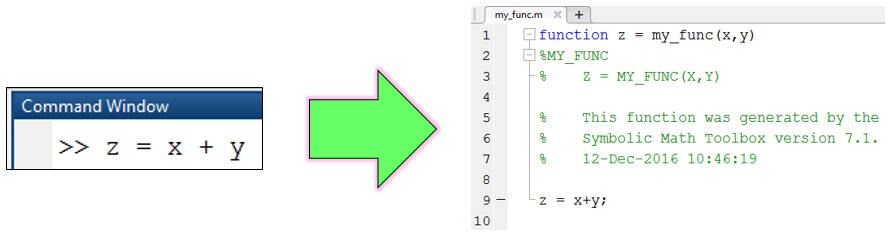

matlabFunction( z,                ...
                'File','my_func', ...
                'Vars', {'x', 'y'});

% look at the autogenerated file
dbtype('my_func.m')   

**Converting symbolic expressions into SIMULINK blocks:**

We can convert also convert symbolic expression into Simulink blocks using the function `matlabFunctionBlock`():

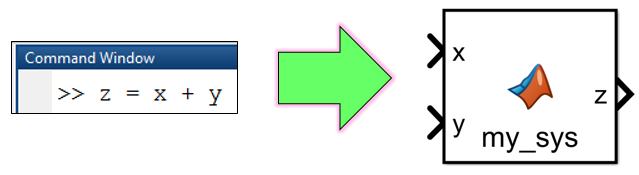

FILENAME        = 'SIM_bh_autogen_z';
BLOCK_NAME      = [FILENAME,'/my_THING'];
new_system(FILENAME)
open_system(FILENAME)

matlabFunctionBlock(BLOCK_NAME, z, 'Vars', {'x', 'y'} );

## A Case Study - part 1:    Deriving the equations of motion

Look at a simple application of Lagrange's equation ... say for simple spring, mass mechanical system:    $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} =Q$

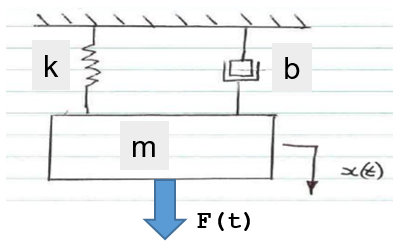

clear; clc

Define some Symbolic variables that we can play with:

syms t x(t) m k b F
syms THE_X THE_XD THE_XDD
actual_list = [       x,   diff(x,t),  diff(x,t,2)];
HOLDER_list = [   THE_X,   THE_XD,     THE_XDD];

Define our system Lagrangian and Generalised force:

v  = diff(x,t);  % velocity
KE = 0.5*m*v^2;  % KINETIC energy
PE = 0.5*k*x^2;  % POTENTIAL energy
L  = KE - PE     % our Lagrangian

$$L(t) = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}-\frac{k\,{x\left(t\right)}^{2}}{2}$$

Q  = F -b*v;     % total NON conservative forces for deltaX

Now let's start applying Lagranges equation $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} $ :

                   % OLD_LIST       NEW_LIST
L_new   = subs(L, actual_list,   HOLDER_list)

$$L\_new(t) = \frac{{{\mathrm{THE}}_{\mathrm{XD}}}^{2}\,m}{2}-\frac{{{\mathrm{THE}}_{X}}^{2}\,k}{2}$$

Our 1st piece is:  $ \frac{\partial L}{\partial x} $

dLdx    = diff(L_new, THE_X)

$$dLdx(t) = -{\mathrm{THE}}_{X}\,k$$

Our 2nd piece is: $\frac{\partial L}{\partial \dot{x}} $

dLdxdot =  diff(L_new, THE_XD)

$$dLdxdot(t) = {\mathrm{THE}}_{\mathrm{XD}}\,m$$

Our 3rd piece is: $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}}$

                                % OLD_LIST      NEW_LIST
dLdxdot       =  subs(dLdxdot, HOLDER_list,  actual_list );
dt_of_dLdxdot = diff(dLdxdot, t)

$$dt\_of\_dLdxdot(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

Now put it all together:   $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} =Q$

our_EOM_LHS = dt_of_dLdxdot - dLdx;

$$our\_EOM\_LHS(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+{\mathrm{THE}}_{X}\,k$$

our_EOM_RHS = Q;

$$our\_EOM\_RHS(t) = F-b\,\frac{\partial }{\partial t}x\left(t\right)$$

our_EOM     = (our_EOM_LHS == our_EOM_RHS);

% display using the actual symbol list
                             % OLD_LIST      NEW_LIST
our_EOM     =  subs(our_EOM, HOLDER_list, actual_list )

$$our\_EOM(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+k\,x\left(t\right)=F-b\,\frac{\partial }{\partial t}x\left(t\right)$$

Now solve for  $\overset{\bullet \bullet }{x}$:

In addition to solving for $\ddot{x}$, we'll show the resulting expression using the "alternate" symbol list:

                              % OLD_LIST      NEW_LIST
our_EOM     =  subs(our_EOM, actual_list,  HOLDER_list);

the_expression_for_XDD = solve(our_EOM, THE_XDD)

And now create a Simulink block for this expression:

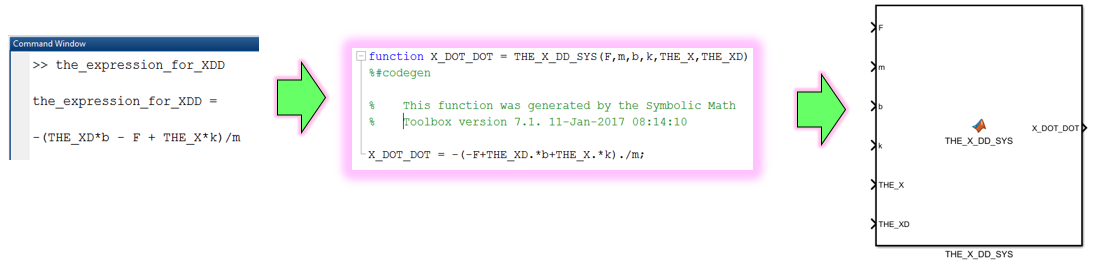

MODEL_NAME        = 'SIM_SMD_WILL_BE_DELETED';
close_system(MODEL_NAME,0)
new_system(MODEL_NAME)
open_system(MODEL_NAME)

matlabFunctionBlock( [MODEL_NAME,'/THE_X_DD_SYS'], the_expression_for_XDD, ...
                         'Vars',     {F, m,b,k,THE_X,THE_XD}, ...
                         'Outputs',  {'X_DOT_DOT'}   ); 

## A Case Study - part 2:    Simulating the model

Let's use the model that we just derived, and implement it in Simulink - where we'll numerically solve it.  The parameters that we'll use for this Numerical simulation are:

  
$$\thinspace\ddot{x}(t) + 4 \thinspace.\thinspace\dot{x}(t) + 100 \thinspace.\thinspace x(t) = 200.u(t-5)$$
   

with   $\matrix{\bullet  \quad x(0) = 5 \cr
\bullet \quad \dot{x}(0) = 0}$

Have a look at our Simulink model .... and NOTE how we use the integrator blocks to integrate:   $\ddot{x} \to \text{ }\frac{1}{s}\text{ }\to \dot{x} \to \text{ }\frac{1}{s}\to x$

open_system('bh_a_spring_mass_model')